# Make plots after RND filtering


%% import the data if already converted to ANA
dir= 'E:\PhD\Adamantane_data\data\Ada_PEPICO_hv287p1eV_ke260_0002\Ada_PEPICO_hv287p1eV_ke260_0002_ana';
raw_data = IO.import_raw(dir);
addpath('E:\PhD\Adamantane_data\mdata')
mdata = md_all();
data            = macro.filter(raw_data, mdata); %define the multiplicity of events
data_corrected = macro.correct(data, mdata);

Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2


data_converted = macro.convert(data_corrected, mdata);

Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2


%Generate RND events
% raw_data = generate_rnd(data,raw_data)

## Get data stats

[data_stats] =get_data_stats(data_converted);

The Scaling factor is 0.45188


## TOF and M2Q spectra All ions

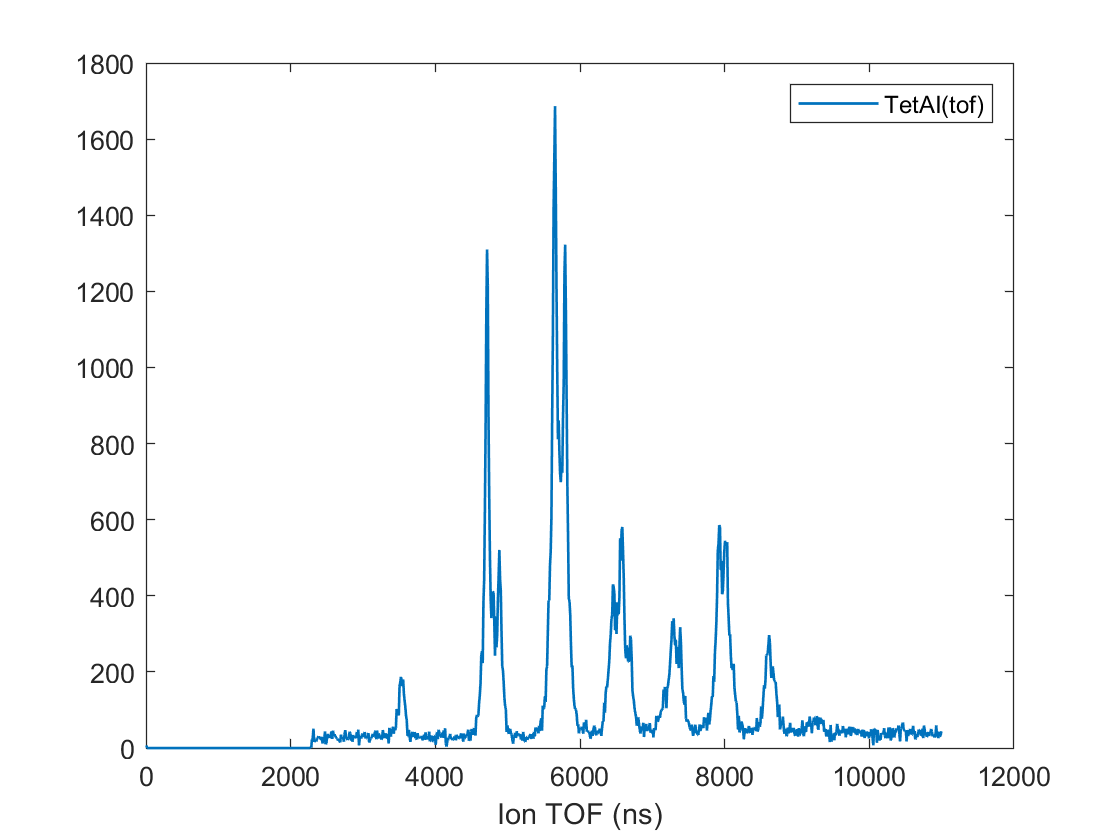

[Tet_tof,Tet_tof_error] = plot_ion_tof(data_converted, data_stats);

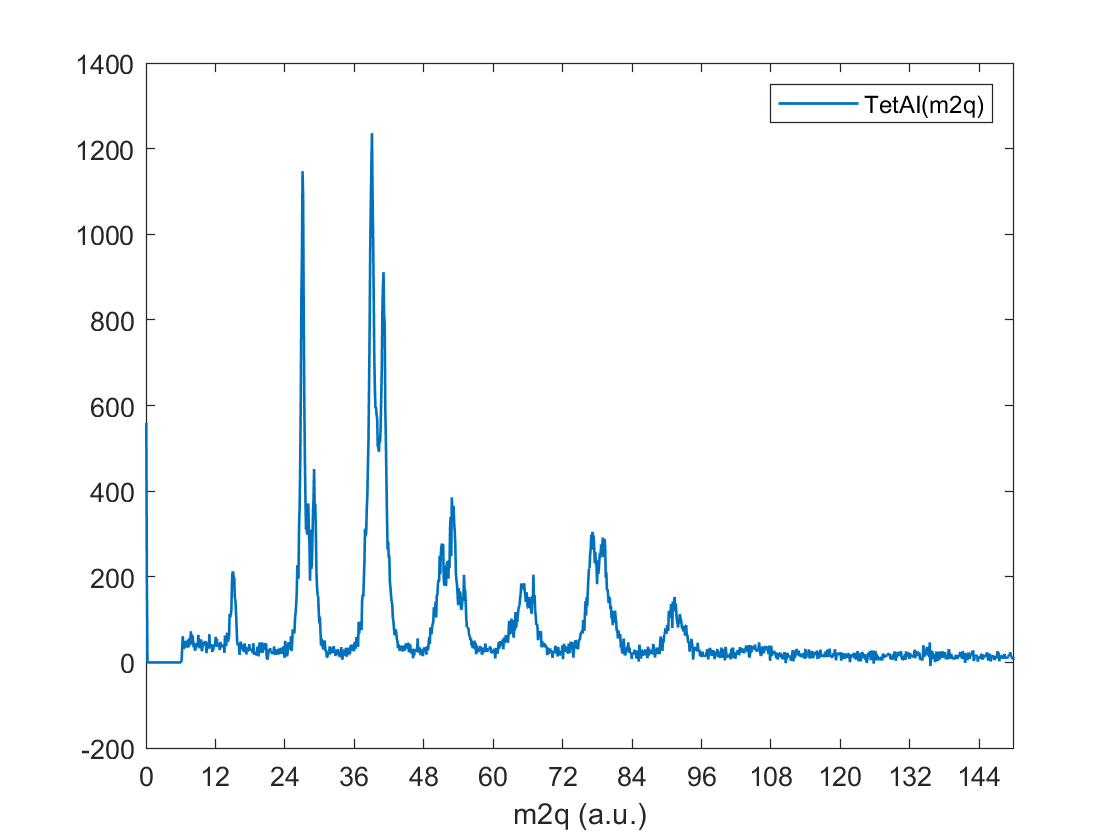

[Tet_m2q,Tet_tof_m2q] = plot_ion_m2q(data_converted, data_stats);

## PIPICO

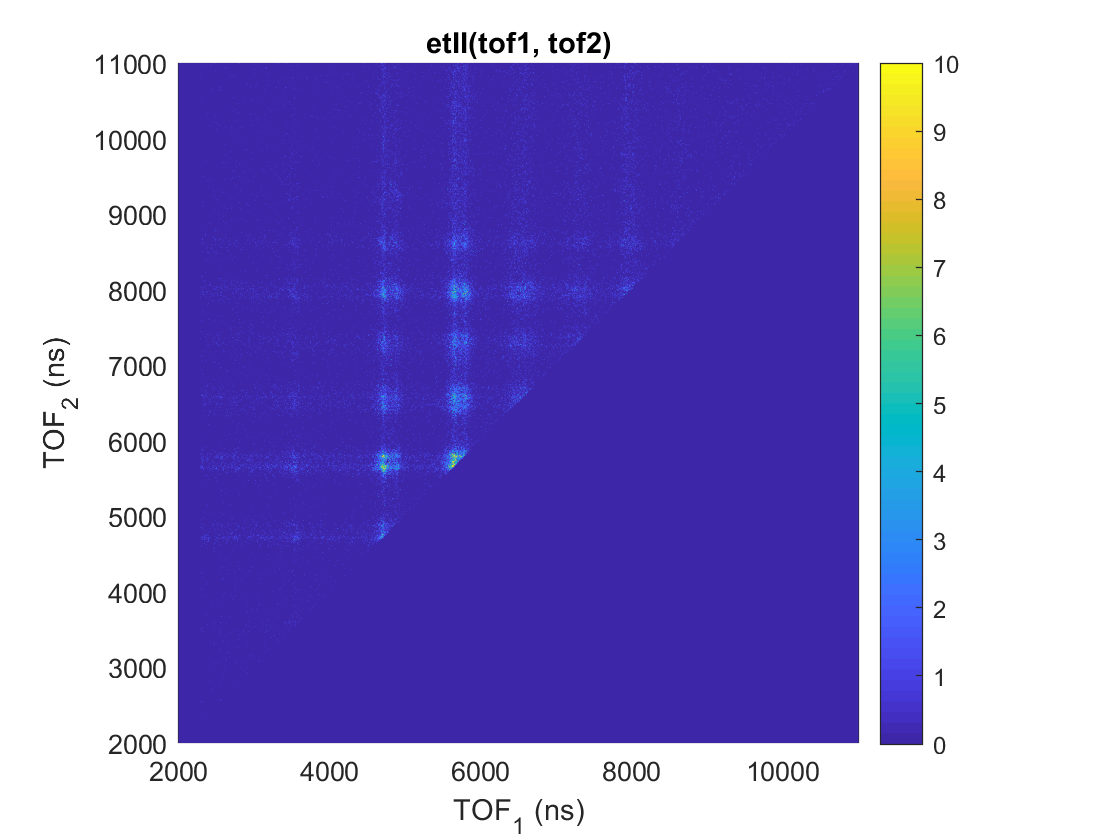

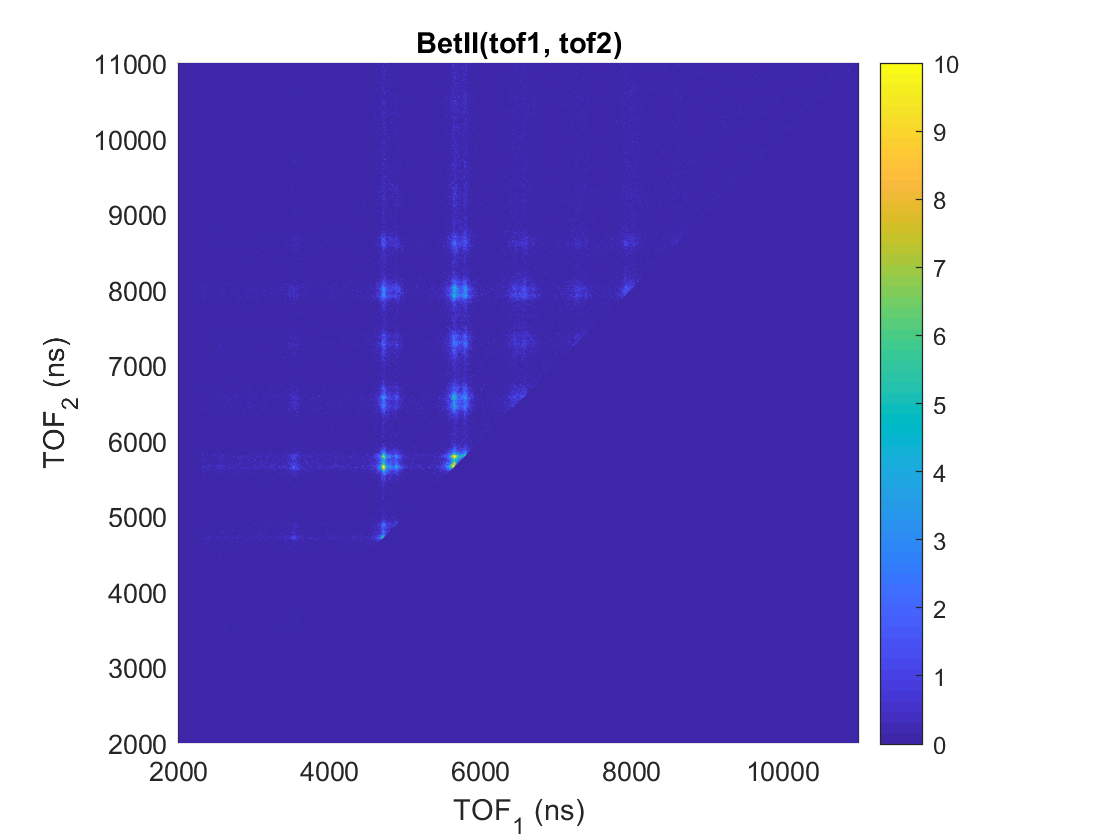

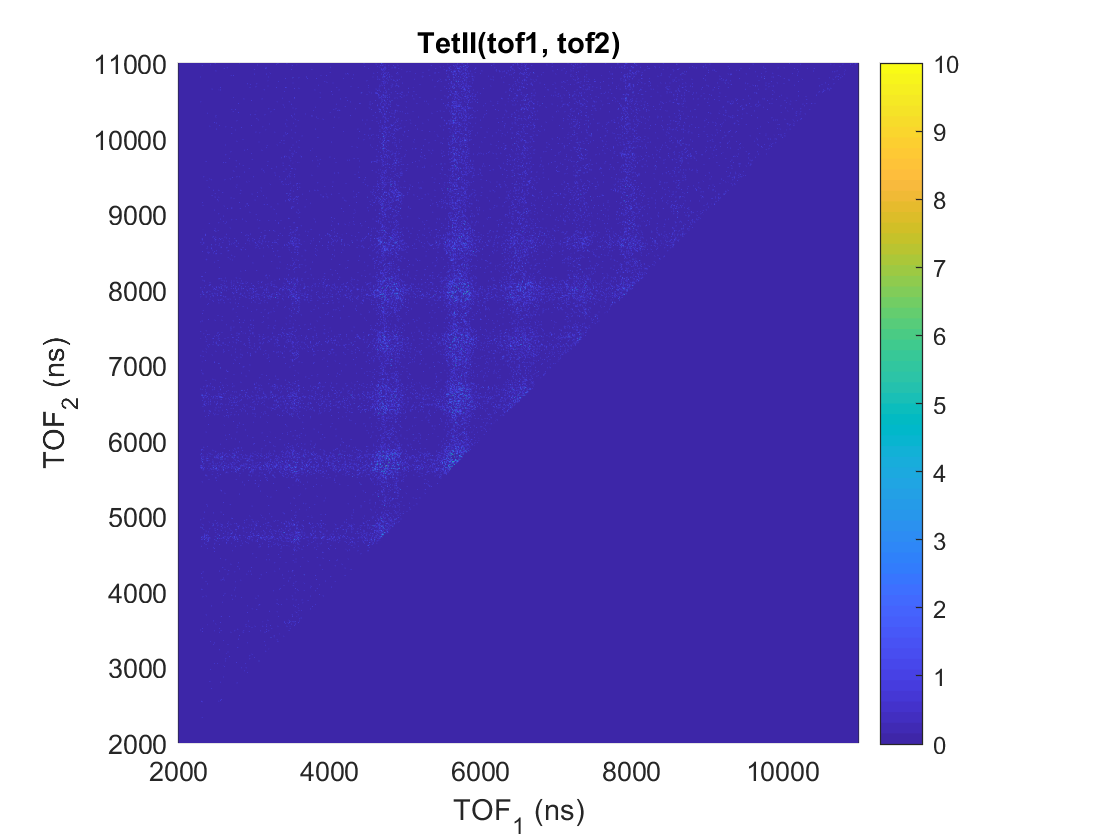

[Tet_tof2] = plot_pipico(data_converted, data_stats);

% [Tet_m2q2] = plot_pipico_m2q(data_converted, data_stats,mdata);
% xlim([10 70])
% ylim([10 100])
% axis square
% caxis([0 30])

## PEPICO

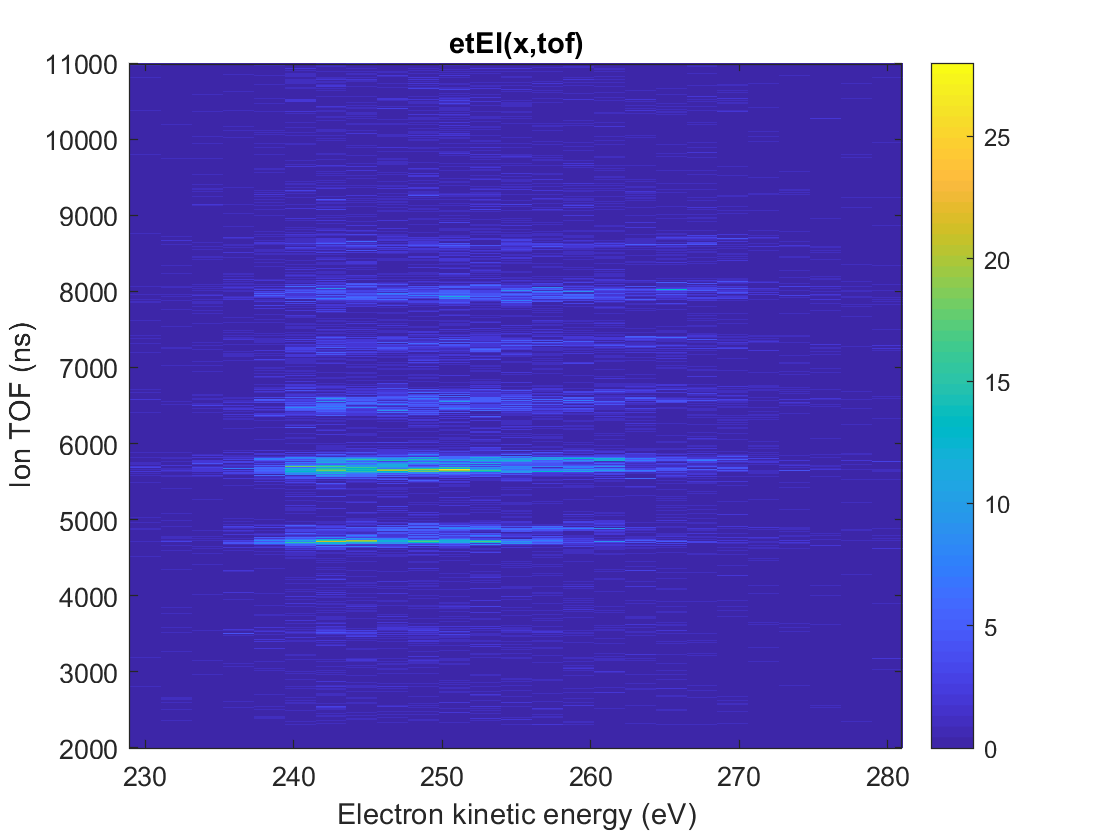

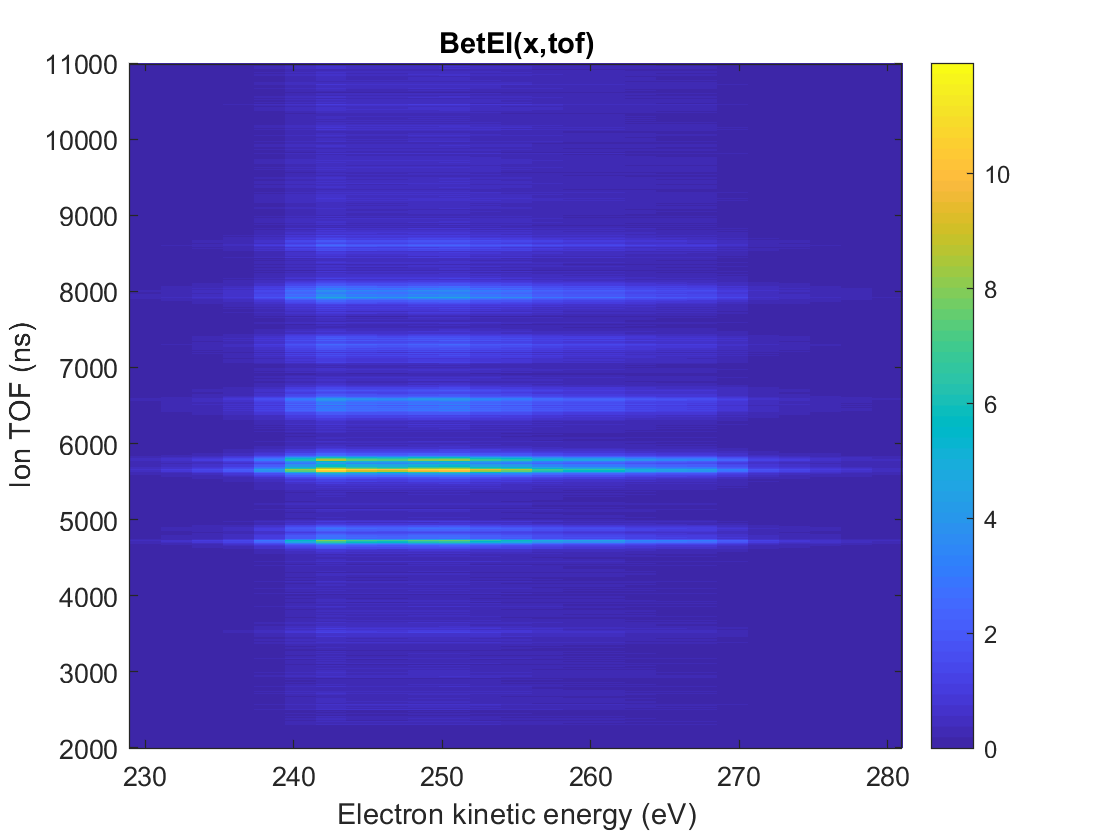

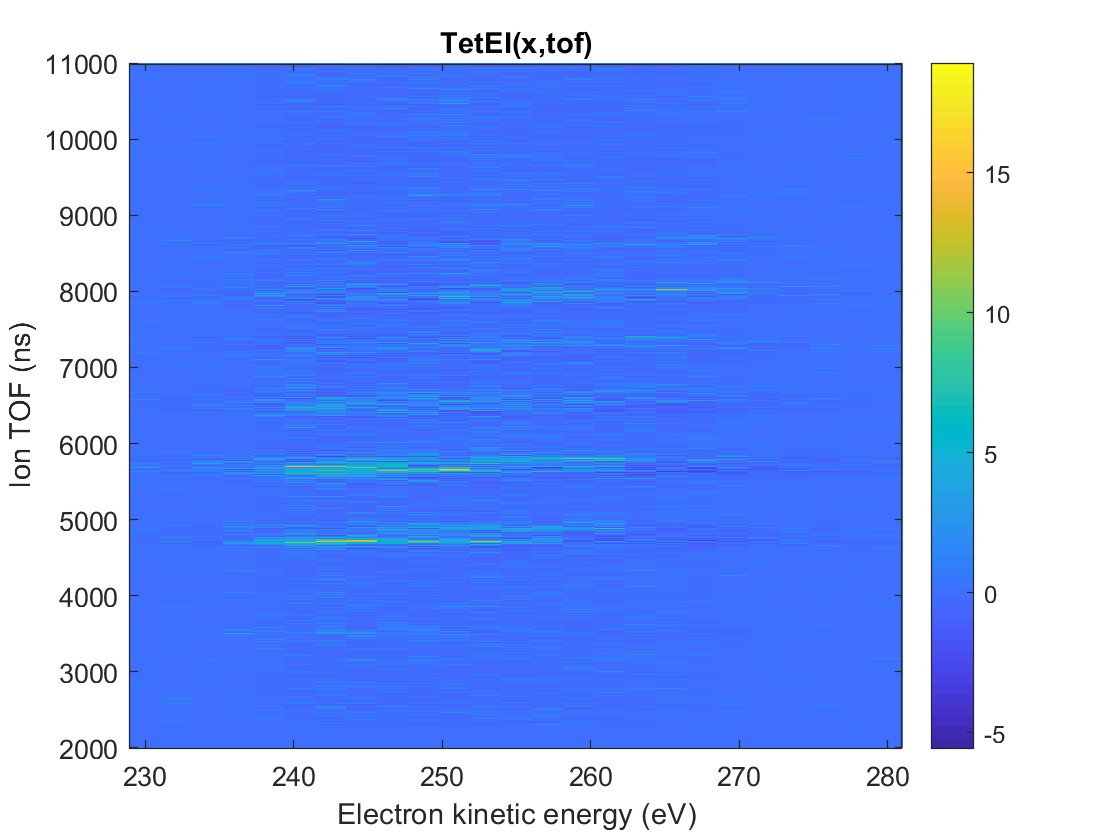

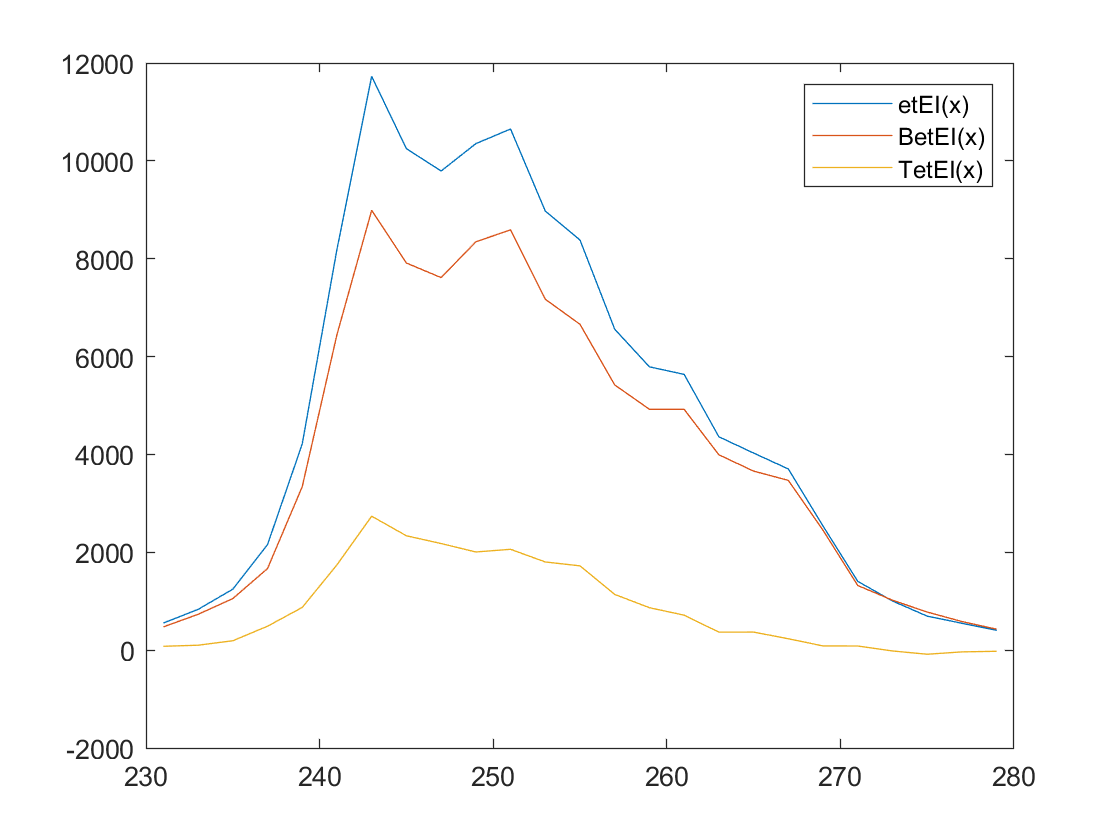


tof_range =[2000 ; 11000];
% tof_range =[4600 ; 5000];

 [TetEI_x_tof,~,~] = plot_pepico(data_converted, data_stats,tof_range);

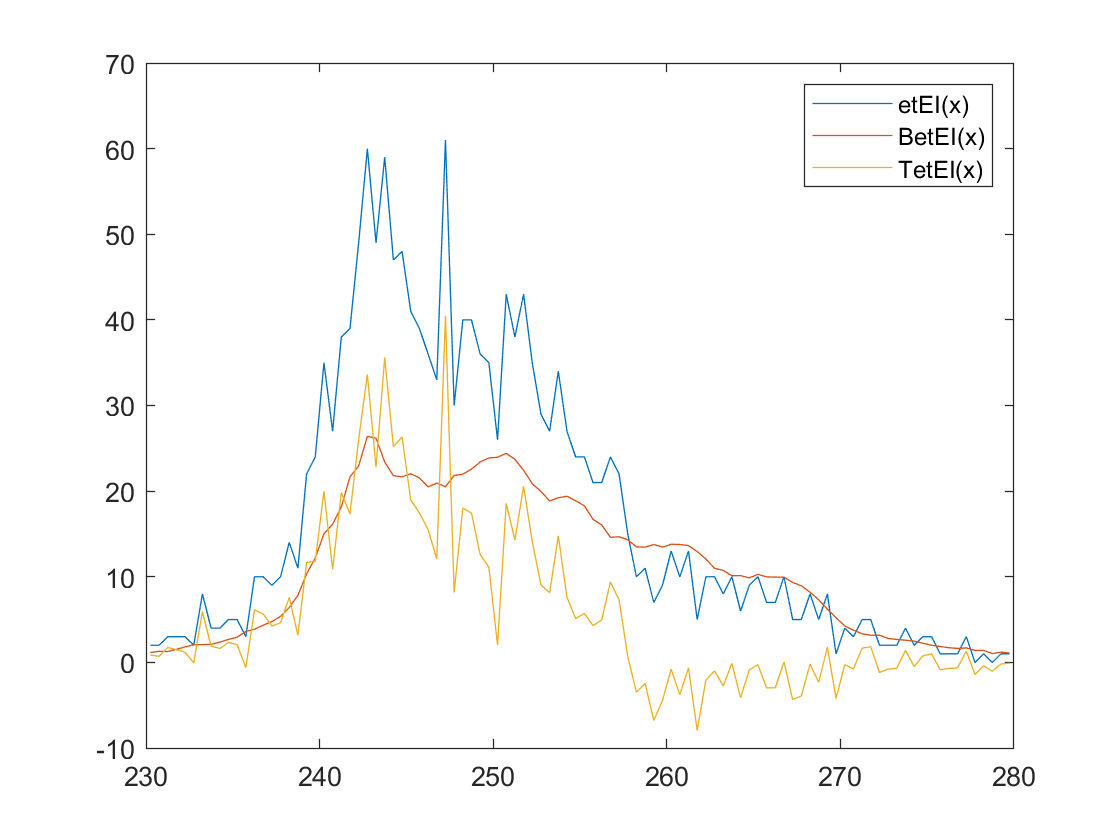

m2q_l = mdata.conv.det2.m2q_label.labels ;
[TetEI_x_m2q,Xedges,Yedges] = plot_pepico_m2q(data_converted, data_stats,m2q_l(1));


% for ii = 1:length(mdata.conv.det2.m2q_label.labels)
%     m2q_l =mdata.conv.det2.m2q_label.labels(ii);
%     [TetEI_x_m2q,Xedges,Yedges] = plot_pepico_m2q(data_converted, data_stats,m2q_l);
%     C_n =min(fix(m2q_l/12),10);
%     label =strcat('C_',num2str(C_n),'H_',num2str(m2q_l-C_n*12),'^+');
%     title(label)
% end

## Select the ion pair

m2q_1 = 12*2+1*5; m2q_2 = 12*8+1*11;
Center(1) = convert.m2q_2_TOF(m2q_1,mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0)

Center = 4.8804e+03

Center(2) = convert.m2q_2_TOF(m2q_2,mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0)

Center = 	1.0e+03 *

    4.8804    9.3222


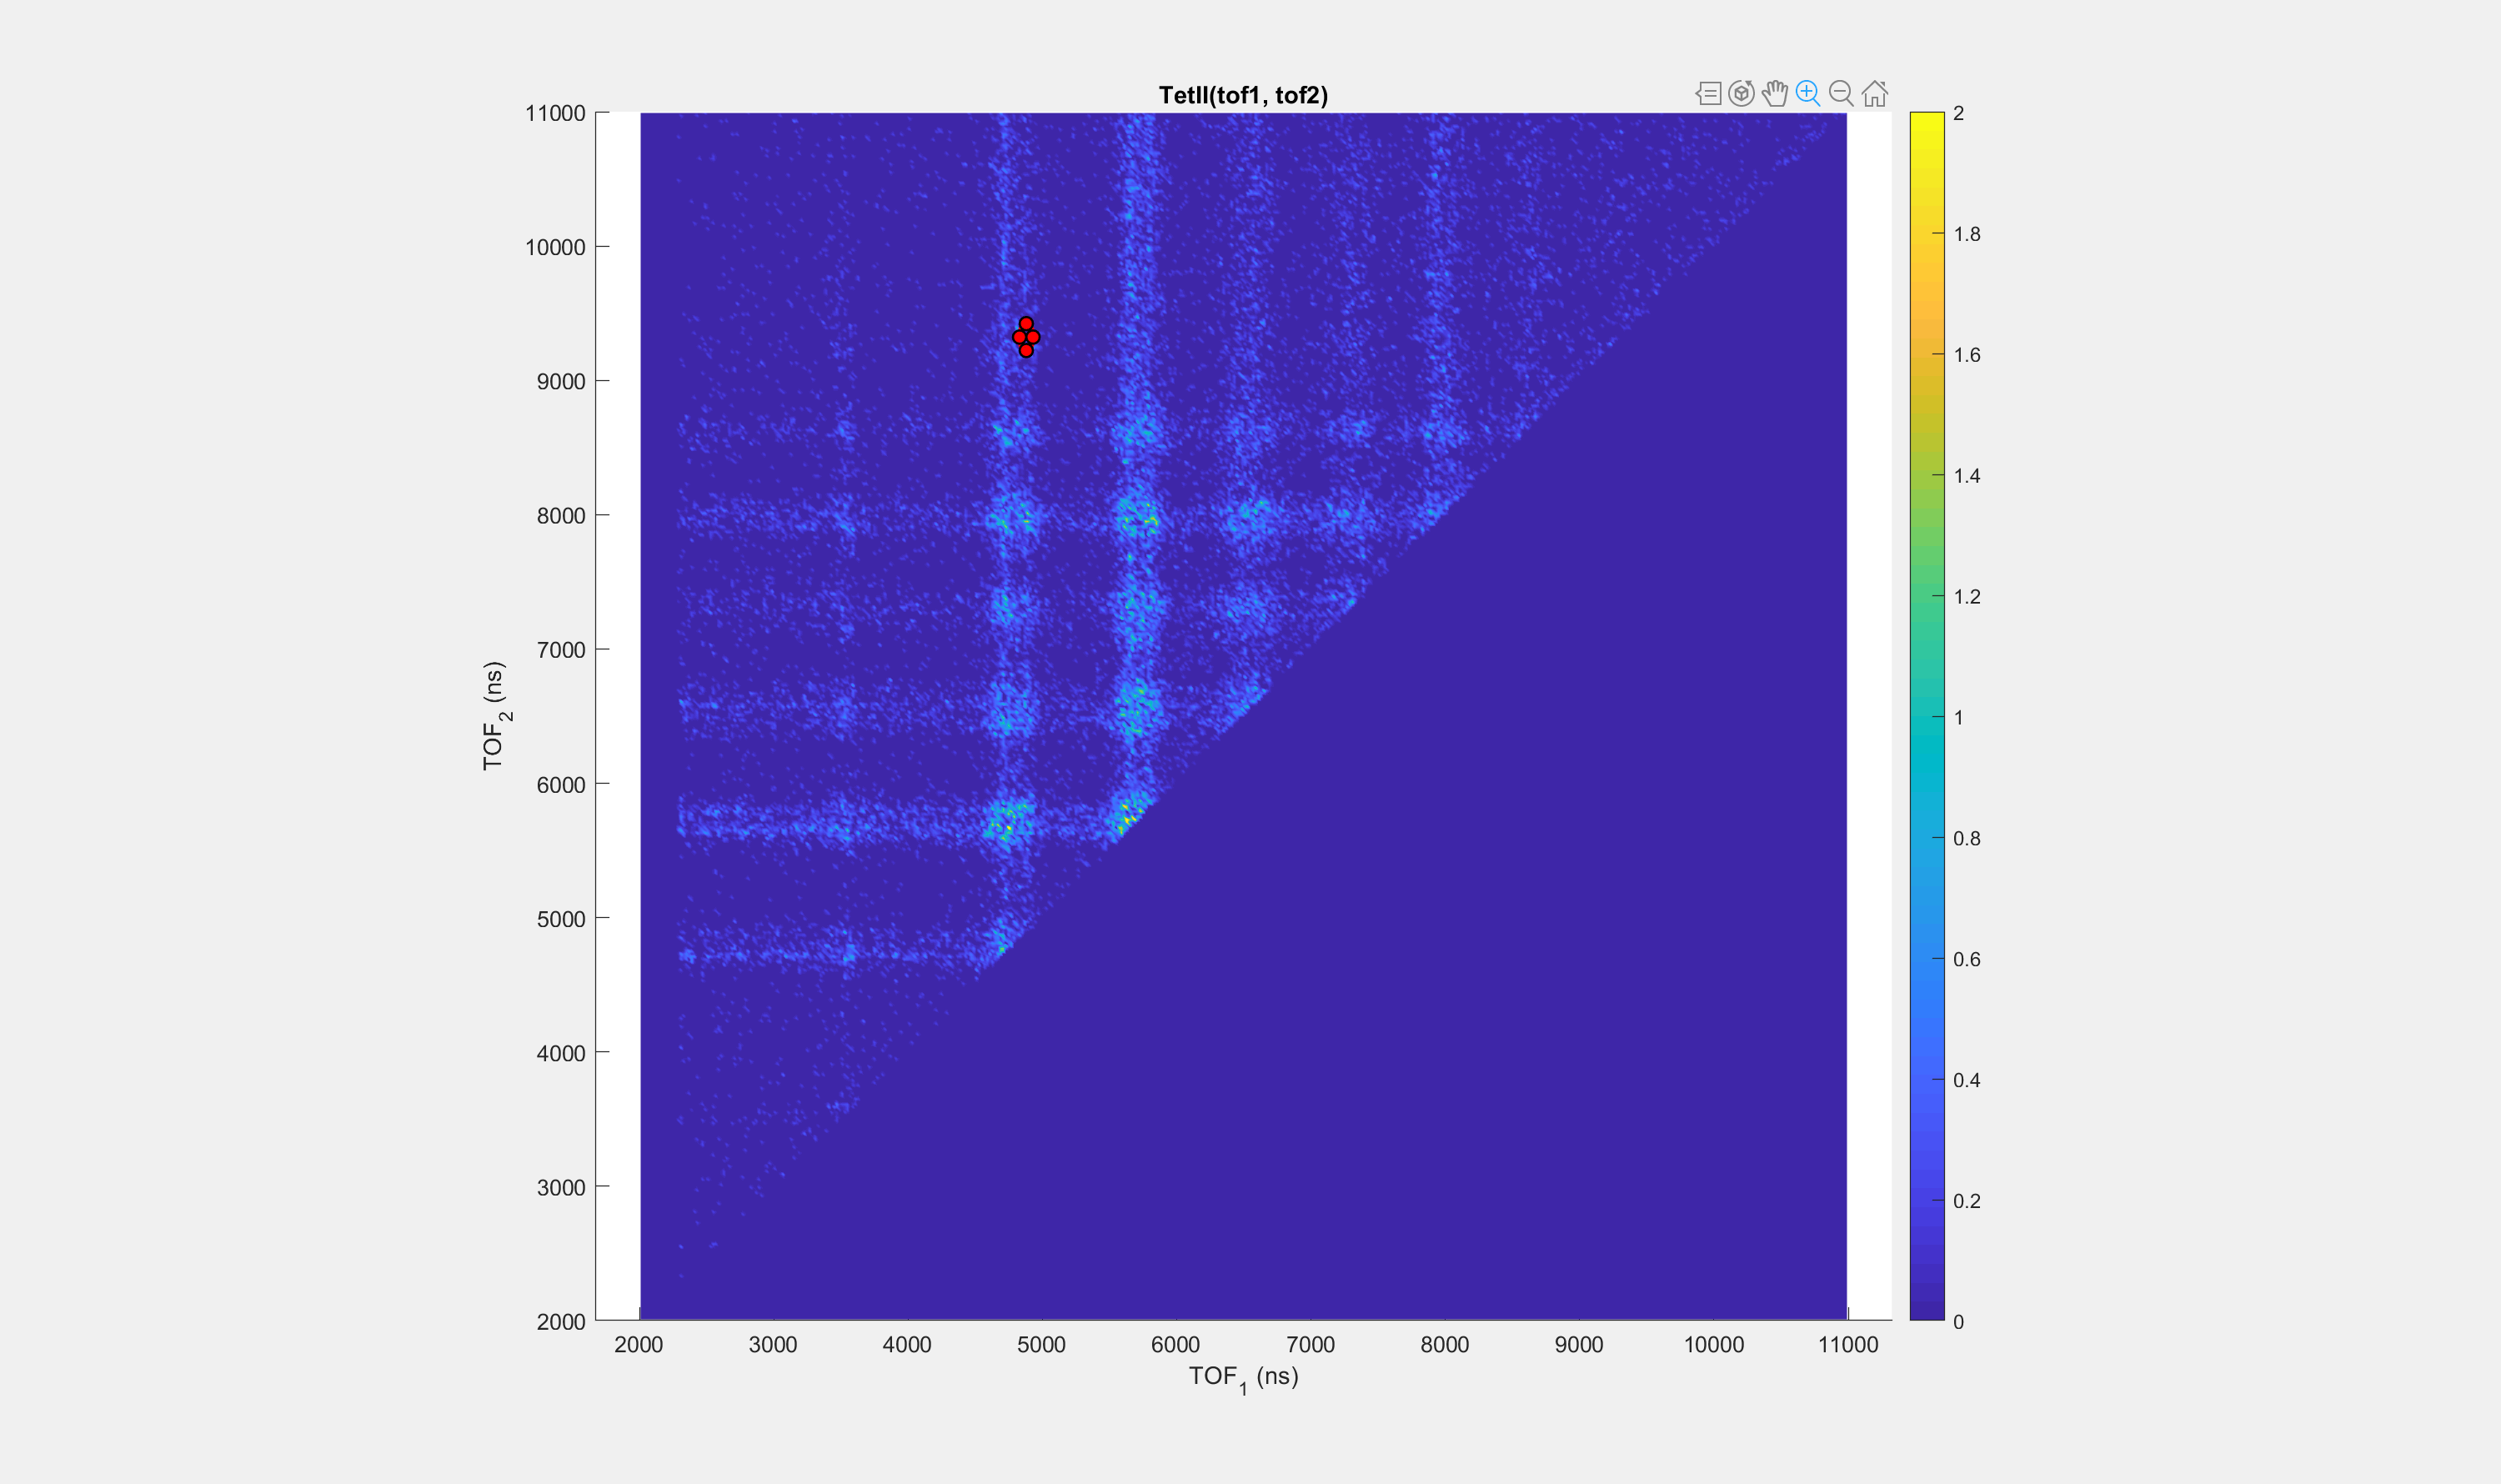


[roi] = get_roi_pipico(data_converted, data_stats,Center);%%

## Ion pair specific Electron Spectra

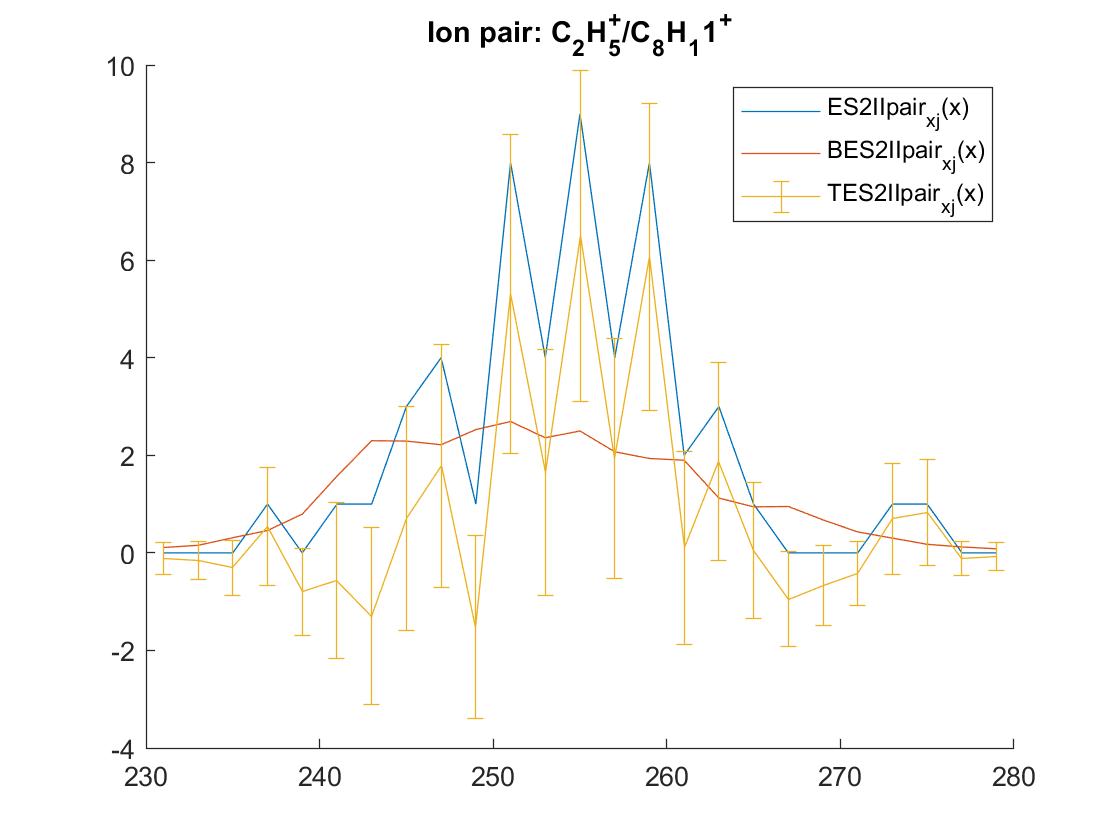


tof_1 =[roi.Center(1)-500 ; roi.Center(1)+500];
tof_2 =[roi.Center(2)-500 ; roi.Center(2)+500];
mdata = md_all();
% macro.plot(data_converted, mdata)
TES2IIpair_x = plot_ES_ion_pair2(data_converted, data_stats,roi,tof_1,tof_2);
%% give name
m2q1 = round(convert.TOF_2_m2q(roi.Center(1),mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0));
m2q2 = round(convert.TOF_2_m2q(roi.Center(2),mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0));
C_n1 =min(fix(m2q1/12),10);
label1 =strcat('C_',num2str(C_n1),'H_',num2str(m2q1-C_n1*12),'^+');
C_n2 =min(fix(m2q2/12),10);
label2 =strcat('C_',num2str(C_n2),'H_',num2str(m2q2-C_n2*12),'^+');
title(['Ion pair: ', label1,'/',label2])